MAX_MOVES = 200;
rng(0,'twister');

Here we will run the experiment for map one

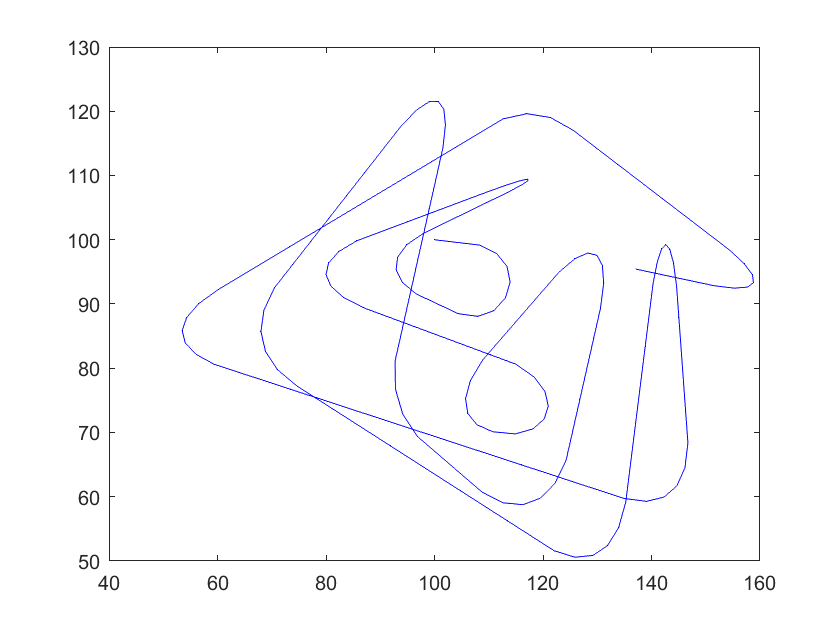

map = makeMap();
drone = Drone(map, 100, 100, 7);
[drone, poses] = Random_Pathfinding_Algorithm(drone, MAX_MOVES);

randomPathfindingStats = getDroneStats(drone, poses)

randomPathfindingStats = struct with fields:
         Percent: 0.1474
    PercentStart: 0.9023
        AvgSpeed: 3.9610


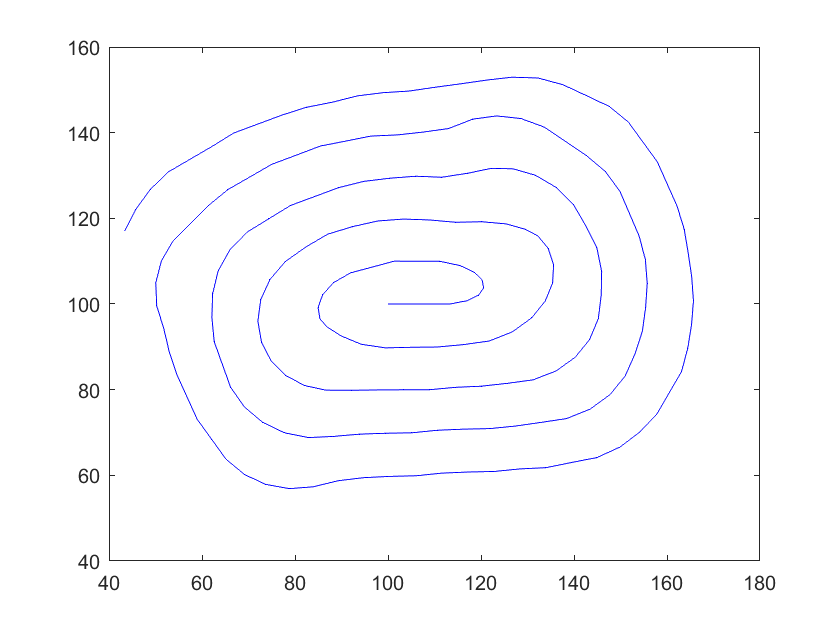

map = makeMap();
drone = Drone(map, 100, 100, 7);
[drone, poses] = Dynamic_Pathfinding_Algorithm(drone, MAX_MOVES);

dynamicPathfindingStats = getDroneStats(drone, poses)

dynamicPathfindingStats = struct with fields:
         Percent: 0.2844
    PercentStart: 0.9850
        AvgSpeed: 5.2142


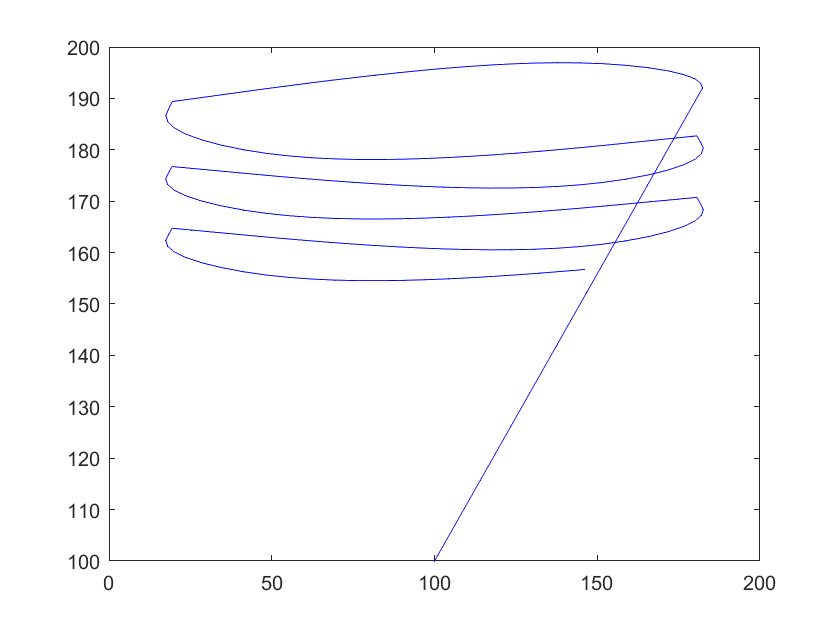

map = makeMap();
drone = Drone(map, 100, 100, 7);
[drone, poses] = Sweep_Search_Algorithm(drone, MAX_MOVES);

sweepPathfindingStats = getDroneStats(drone, poses)

sweepPathfindingStats = struct with fields:
         Percent: 0.2130
    PercentStart: 0.1742
        AvgSpeed: 5.4628


function stats = getDroneStats(drone, poses)
    starting = [size(drone.DroneMap, 1)/2*0.75, size(drone.DroneMap, 1)/2*1.25];
    moves = drone.Moves;
    explored = length(drone.DroneMap(drone.DroneMap>0));
    total = size(drone.DroneMap, 1) * size(drone.DroneMap, 2);
    stats.Percent = explored / total;
    startingArea = drone.DroneMap(starting(1):starting(2), starting(1):starting(2));
    exploredStart = length(startingArea(startingArea>0));
    totalStart = size(startingArea, 1) * size(startingArea, 2);
    stats.PercentStart = exploredStart / totalStart;
    moves = [diff(poses(:,1)), diff(poses(:,2))];
    speed = hypot(moves(:,1), moves(:,2));
    stats.AvgSpeed = mean(speed);
end
function map = makeMap()
    map = rand(200, 200);
    map(map==0) = 0.5;
end